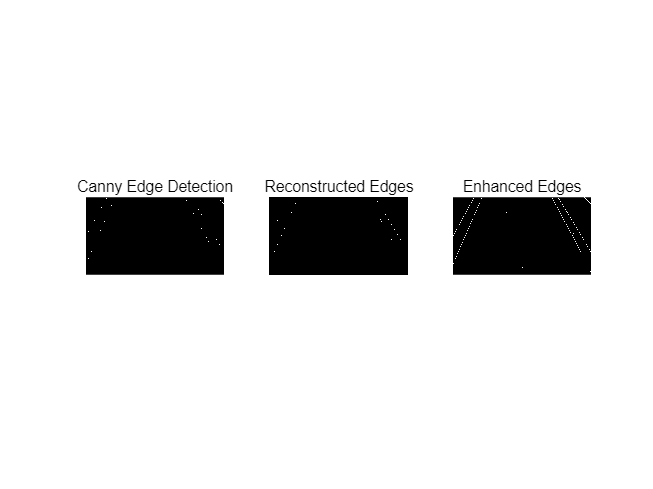

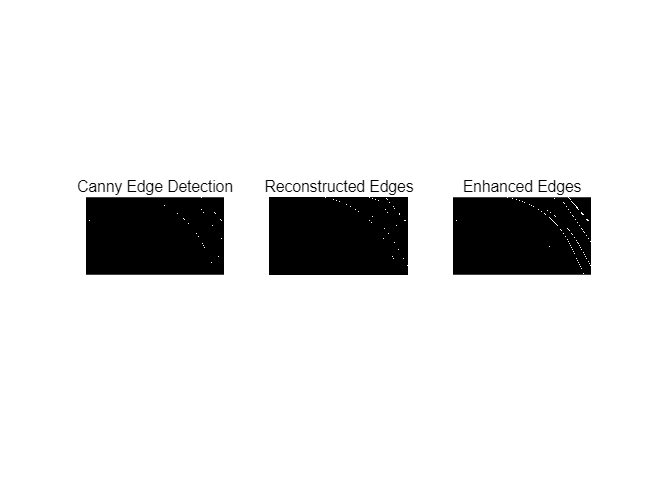

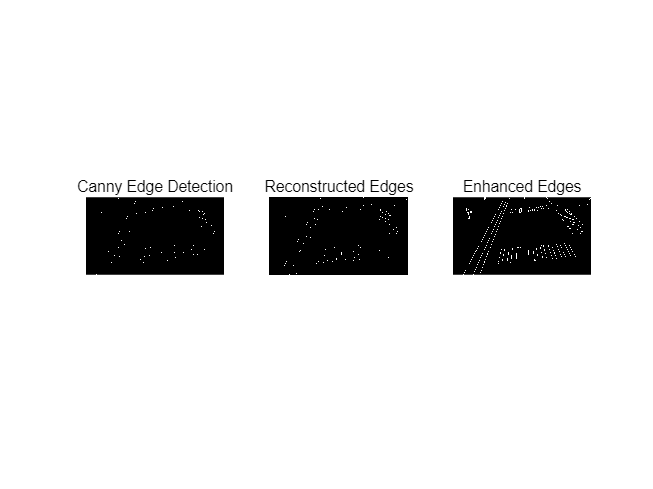

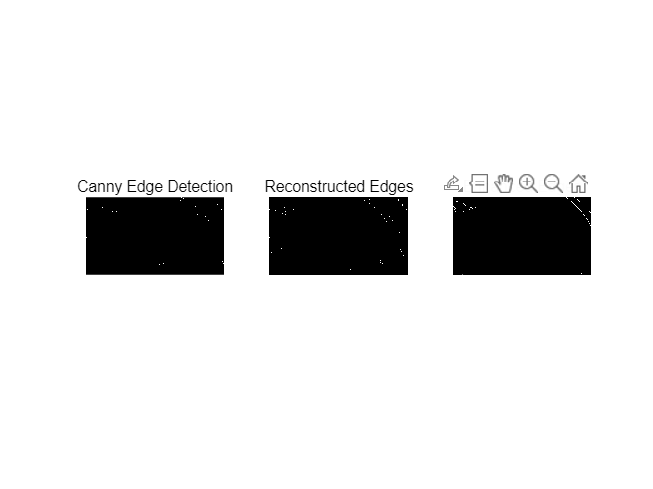

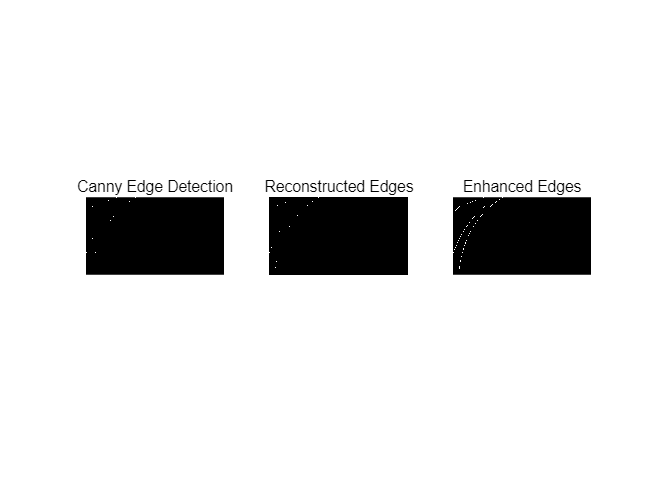

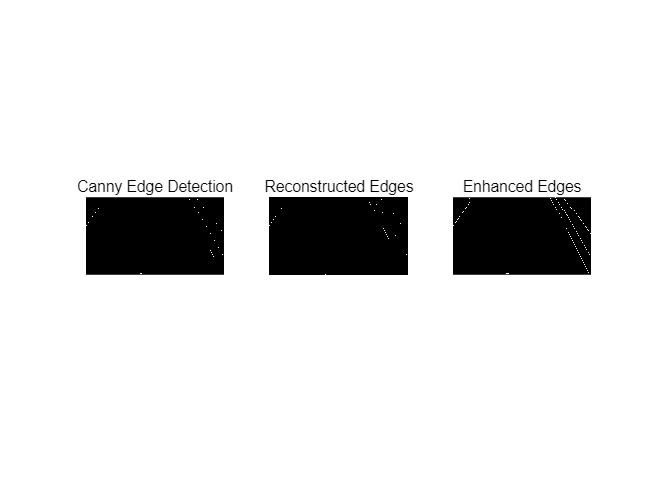

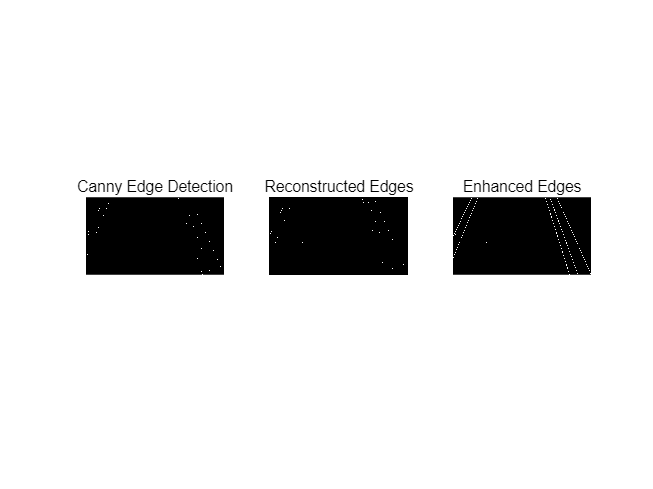

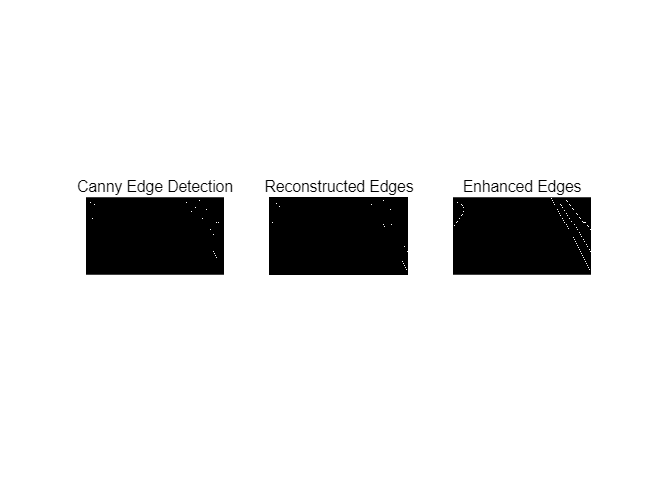

% 设置图片文件夹路径
folderPath = 'C:\Users\DELL\Desktop\底特律大学\第二学期\experiment\picture';

% 获取文件夹中所有图片文件
imageFiles = dir(fullfile(folderPath, '*.jpg')); % 可根据需要更改为 '*.png', '*.bmp'

% 检查是否有文件

% 遍历每张图片
for i = 1:length(imageFiles)
    % 获取图片完整路径
    imgPath = fullfile(folderPath, imageFiles(i).name);
    
    % 读取图片
    img = imread(imgPath);
    
    % 转换为灰度图像
    grayImg = rgb2gray(img);
    
    % 去噪处理（双边滤波）
    blurImg = imbilatfilt(grayImg); % 双边滤波去噪
    
    % 边缘检测（Canny）
    cannyEdges = edge(blurImg, 'Canny', [0.2, 0.4]); % 调整阈值捕获更多边缘
    
    % 使用形态学腐蚀生成种子图像
    se = strel('rectangle', [1,2]); % 结构元素大小可调整
    marker = imerode(cannyEdges, se); % 生成种子图像
    
    % 使用种子图像和掩膜图像进行重构
    reconstructedEdges = imreconstruct(marker, cannyEdges);
    
    % 可选：对重构结果进行膨胀增强
    enhancedEdges = imdilate(reconstructedEdges, strel('rectangle', [2,6]));
    
    % 创建子图，集中展示处理结果
    figure('Name', ['Processing Results: ', imageFiles(i).name], 'NumberTitle', 'off');
    
    % 边缘检测结果
    subplot(1, 3, 1);
    imshow(cannyEdges);
    title('Canny Edge Detection');
    
    % 重构后的边缘图像
    subplot(1, 3, 2);
    imshow(reconstructedEdges);
    title('Reconstructed Edges');
    
    % 膨胀增强后的边缘图像
    subplot(1, 3, 3);
    imshow(enhancedEdges);
    title('Enhanced Edges');

end